clc
clear all
close all
addpath("functions")



## **1. GP complexity**

This section of the code is dedicated to answering question 3.1 and all its 5 sub-questions.

%Assigning given values
hyp = [0.05;1]; %defining hyper parameters
Nd = [10 15 20];%different Nd values for data generation

#### Testing GPregression for differently sized data sets

for i = 1:length(Nd)
    %generate dataset
    [X,y,Xstar] = getdata(Nd(i),hyp);
    if Nd(i) == 10
        X1 = X;
        y1 = y;
        Xstar1 = Xstar;
    end

    %Perform GP regression, time it and calculate the models mean and covariance for
    %new points and kernel matrix for training points.
    tic
    [GPmodel,predictions,mean, cov, k_matrix] = GPregression(X,y,Xstar,hyp);
    elapsed_time = toc;

    %Save relevantdata in results parameter.
    results.GPmodel = GPmodel;
    results.predictions = predictions;
    results.mean = mean;
    results.cov = cov;
    results.k_matrix = k_matrix;
    results.elapsed_time = elapsed_time;
    results.Nd = Nd(i);
    

    %allocate output of the model
    GP_data{i} = results;
end

#### Plotting 3D results for N=1000

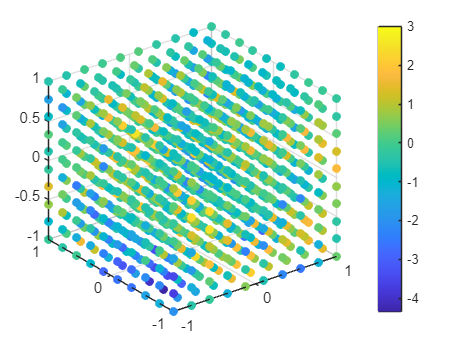

%Getting predictions of model for Nd = 10
preds = GP_data{1}.predictions;

%3D scatterplot of data + colorbar
scatter3(X1(:,1),X1(:,2),X1(:,3),[],y1,'filled')
colorbar;

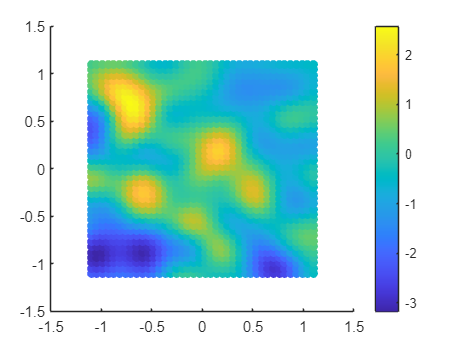


%Scatterplot of predictions
scatter(Xstar1(:,1),Xstar1(:,3),[],preds,'filled')
colorbar;

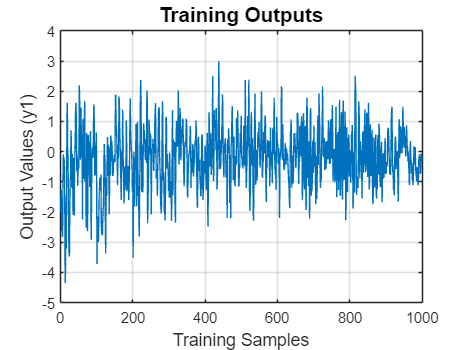


%Additional plots to understand the data and for the report
figure; %Output data plot
plot(y1); 
title('Training Outputs', 'FontSize', 14);
xlabel('Training Samples', 'FontSize', 12);
ylabel('Output Values (y1)', 'FontSize', 12);
grid on;

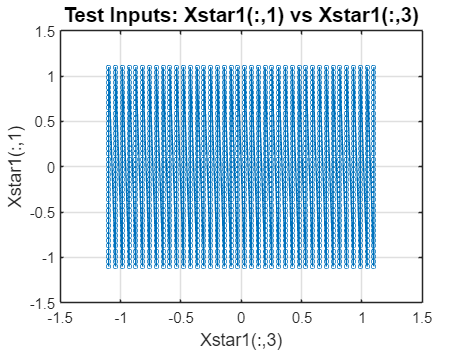


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), Xstar1(:,1),'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) vs Xstar1(:,3)', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('Xstar1(:,1)', 'FontSize', 12); 
grid on;  

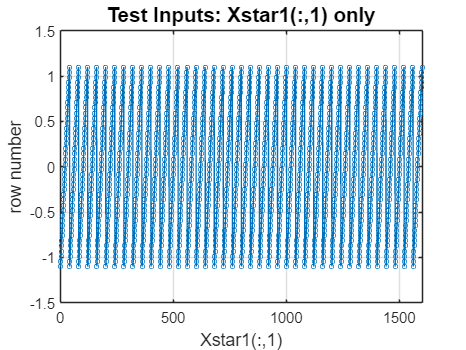


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,1), 'o-',  'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) only', 'FontSize', 14);
xlabel('Xstar1(:,1)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;  

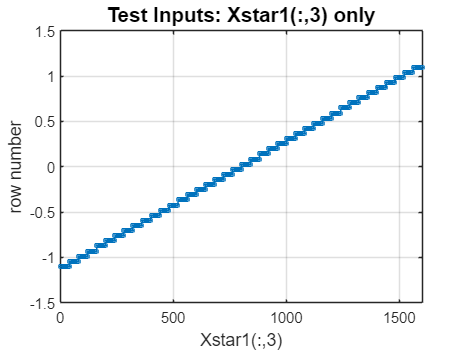


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), 'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,3) only', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;

## 2. Kernel Matrix as Tensor Train

K = GP_data{1}.k_matrix; %Kernel matrix for 10^3 inputs.
I_sz = [10 10 10]; J_sz = [10 10 10];
K_tensor = reshape(K,[I_sz, J_sz]);
